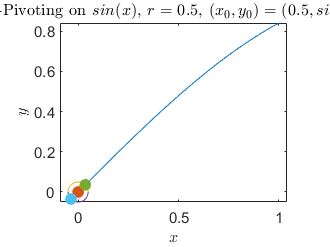

f = @(x) sin(x);

r = 0.05;
x0 = 0;
y0 = f(x0);

circ_top = @(x, x0, y0) y0 + sqrt(r.^2 - (x - x0).^2);
circ_bot = @(x, x0, y0) y0 - sqrt(r.^2 - (x - x0).^2);

f2_1 = @(x) circ_top(x, x0, y0);
f2_2 = @(x) circ_bot(x, x0, y0);

x = linspace(0, 1, 100);
plot(x, f(x))

hold on
scatter(x0, y0, 50, "filled")
x_new = linspace(x0 - r, x0 + r, 100);
plot(x_new, f2_1(x_new), x_new, f2_2(x_new));
axis equal

f_zer1 = @(x) f(x) - f2_1(x);
f_zer2 = @(x) f(x) - f2_2(x);

x1 = fzero(f_zer1,x0);
x2 = fzero(f_zer2,x0);

scatter(x1, f(x1), 50, "filled")
scatter(x2, f(x2), 50, "filled")
hold off

xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")

title("Ball-Pivoting on $sin(x)$, $r = 0.5$, $(x_0, y_0) = (0.5, sin(0.5))$", "Interpreter","latex")
saveas(gcf, "demo.pdf")